clear; clc;
M = readmatrix("Sigma_data.csv");
M(isnan(M)) = 0;

BendMoment = readmatrix('BendingMoment.csv');
Loc = BendMoment(:,1);
BM = BendMoment(:,2);

File3 = readmatrix('Loc_V_T.csv');
Vn = File3(:,2);
Torque = File3(:,3);
loc2 = File3(:,1);

SPARS = readmatrix('k_spars.csv');
platAR = SPARS(:,1);
KS_list = SPARS(:,2);

T_OEI = readmatrix('TorqueOEI.csv');
TorqueOEI = T_OEI(1,:);
locOEI = T_OEI(2,:);

% N,h, ts_t, BM, Vn, Torque, Loc,M,yield
N = 15;
h = 0.057%0.024;

h =    0.057000000000000


ts_t = 0.6;
yield = 440e6;
trescaYield = 484e6 / 2; % Half of the tensile yield stress
combined = false; % False if it works

format long;
Ncrit=false;
E = 73.8e9; %72.4e9;

root_chord = 4.027;
box_width_root = (0.6-0.15)*root_chord;
web_flange = 0.3; 
pannel_width = box_width_root / N

pannel_width =    0.120810000000000


h_b = h / pannel_width

h_b =    0.471815247082195


h_root = h;
d_root = (web_flange * h_root)

d_root =    0.017100000000000



% Check that K > 3.62 at root
Kroot = K_interp(h_b, ts_t,M);

% Wing box modification to reduce NC
% Fuselage diameter = 2.786
modL = 2.786/2+ 0.2;
boxW_root= 1.9;
boxH_root = 0.4;

boxW_mod = (4.027 - 0.1713.*modL) * (0.6-0.15);
boxH_mod = (4.027 - 0.1713.*modL) * (0.0989+0.0879)/2;
mMod = (boxH_root - boxH_mod) / -modL;
mModW = (boxW_root - boxW_mod) / -modL;

y = 0;
ribsVol = 0;
sparsVol = 0;
i = 1;

% ts is determined by max stress location, which now at interface of
% changing box structures
box_heightJoin = boxH_root + mMod * y;
box_widthJoin = boxW_root + mModW * y;
NC = interp1(Loc, BM, modL) / (box_widthJoin * box_heightJoin);
t2max = (NC * (pannel_width^2) / (3.62 * E)) ^ (1/3)

t2max =    0.005415336630682


ts_set = ts_t * t2max

ts_set =    0.003249201978409


ts_set = ceil(10000*ts_set)/10000;

while y < 14.1
    if y < modL
        box_height = boxH_root + mMod * y;
        box_width = boxW_root + mModW * y;
        chord = (4.027 - 0.1713*y);
        box_heightOld = chord*(0.0989+0.0879)/2;
        box_widthOld = (0.6-0.15)*chord;
    else
        box_height = chord*(0.0989+0.0879)/2;
        box_width = (0.6-0.15)*chord;
    end
    
    NC = interp1(Loc, BM, y) / (box_width * box_height);
    t2 = (NC * (pannel_width^2) / (3.62 * E)) ^ (1/3);
    % Important that this calculated t2 is used when calculating sigma P
    % Regarsless of what the minumum thickness actuall is
    t2_real = ceil(10000*t2)/10000;
    if t2 < 0.001
        t2_real = 0.001;
    end

    %disp(t2)
    %disp(t2_real)

    if i == 1
        % If at the root, calculate stringer thickness
        if t2max > t2
            ts_root = ts_set
        else
            ts_root = ts_t * t2
        end
        As_root = (h_root + 2*d_root)*ts_root
    end
    
    T_eq = t2_real + As_root/pannel_width;  % TODO should be t2_real
    actual_stress(i) = NC/T_eq;
    NCS(i) = NC;
    NCS_old(i) = interp1(Loc, BM, y) / (box_widthOld * box_heightOld);
    T_eqList(i) = T_eq;
    ribLoc(i) = y;
    t2SpanwiseReal(i) = t2_real;
    t2Calc(i) = t2;

    
    % Recalculate As/bt, not sure if i should use t2_real or t2
    As_bt = As_root / (pannel_width * t2_real);
    ts_t = ts_root / t2;

    ts_tReal = ts_root / t2_real;

    % Now read of buckling factor for pannel
    K = K_interp(h_b, ts_t,M);
    K_real = K_interp(h_b, ts_tReal,M);
    % IF the ts/t > 2 then K is capped at the ts/t = 2 curve, as it is not
    % realistic to have buclking factors > 6
    Ks(i) = K;
    %FInt = farrarFunc(As_bt,ts_t) %0.82; % Set to a constant (conservative estimate)
    I_A = h^2 * h_b * ts_t * (0.633+ 0.37* h_b* ts_t) / (1.6 *h_b * ts_t + 1)^2;
    F = ((K * (t2/pannel_width)^2 * pi^2 * I_A)^(1/4) ) / (t2* (1 + 1.6*h_b * ts_t))^(1/2);
    
    I_A_real = h^2 * h_b * ts_tReal * (0.633+ 0.37* h_b* ts_tReal) / (1.6 *h_b * ts_tReal + 1)^2;
    F_real = ((K_real * (t2_real/pannel_width)^2 * pi^2 * I_A)^(1/4) ) / (t2_real* (1 + 1.6*h_b * ts_tReal))^(1/2);
    FarrarsReal(i) = F_real;
    % Reasonable esitmate for observed trends

    % Calculate pannel buckling stress, from the t2 calculated (do NOT use
    % the corrected one, t2_real)

    sigma_p = K * E * (t2/pannel_width) ^ 2;
    sigmaPs(i) = sigma_p;
    sigma_pReal = K_real * E * (t2_real/pannel_width) ^ 2;
    sigmaPsReal(i) = sigma_pReal;

    % Calculate rib spacing, to ensure pannel buckling stress = stringer
    % buckling stress
    %Lprev = L;
    L = NC * E * (F / sigma_p) ^ 2;
    %L = NC * E * (F_real / sigma_pReal) ^ 2;

    %L_real = NC * E * (F_real / sigma_pReal) ^ 2;
    %sigma_L(i) = F * sqrt( NC * E /L);
    %sigma_LReal(i) = F * sqrt( NC * E /L_real);
    Ls(i) = L;
    %LsReal(i) = L_real;

    % Rib thickness calculation
    L_b2 = L / box_height;
    if L_b2 < 1
        L_b2 = 1/L_b2;
    end
    
    %K_s = 0.0339*L_b2^4 - 0.5549*L_b2^3 +3.3584*L_b2^2 -9.0158*L_b2+14.296;
    if L_b2 < 6
        K_s = interp1(platAR, KS_list, L_b2);
    else
        K_s = 8.1;
    end
    q_v = interp1(Loc, Vn, y) / (2*box_height); % Shear flow due to shear force
    %q_T = interp1(Loc, Torque, y) / (2*box_width*box_height); % Shear flow due to torque
    q_TOEI = interp1(locOEI, TorqueOEI, y) / (2*box_width*box_height);
    q_FSOEI = abs(q_v + q_TOEI);
    q_RSOEI = abs(q_v - q_TOEI);
    t_FSOEI = ((q_FSOEI*box_height^2/(K_s*E))^(1/3));
    t_RSOEI = ((q_RSOEI*box_height^2/(K_s*E))^(1/3));
    sparK(i) = K_s;

    q_T = interp1(Loc, Torque, y) / (2*box_width*box_height); % Shear flow due to torque
    q_FS = abs(q_v + q_T);
    q_RS = abs(q_v - q_T);
    t_FS = ((q_FS*box_height^2/(K_s*E))^(1/3));
    t_RS = ((q_RS*box_height^2/(K_s*E))^(1/3));

    t_FS_real(i) = t_FS;
    t_RS_real(i) = t_RSOEI;

    t_RS = ceil(10000*max(t_RS,t_RSOEI))/10000;
    t_FS = ceil(10000*max(t_FS,t_FSOEI))/10000;

    tau_FS(i) = q_FS / t_FS;
    tau_RS(i) = q_RS / t_RS;

    if t_FS < 0.001
        t_FS = 0.001;
    end
    if t_RS < 0.001
        t_RS = 0.001;
    end

    frontSpars_t(i) = t_FS;
    rearSpars_t(i) = t_RS;
    
    % Calculate I of the cover
    I  = (box_width * T_eq^3)/12 + box_width * T_eq * (box_height/2)^2;
    F_rib = (interp1(Loc, BM, y))^2 * L * box_height * T_eq * box_width / (2 * E * I^2);
    t_r = ((F_rib * box_height^2 / (3.62 * E * box_width)) ^ (1/3));
    t_r= ceil(10000*t_r)/10000;
    if t_r < 0.001
        t_r = 0.001;
    end

    rib_t(i) = t_r;
    % Ribs volume
    ribsVol = ribsVol + t_r * box_width * box_height;
    crush_stress = F_rib /(t_r * box_width);

    % Next rib is placed
    y = y + L;
    if y > 14.1
        break
    end
    
    % Calculate spars volume using average of box heights at the current
    % new and old ribs
    chord = (4.027 - 0.1713*y);
    box_height2 = (chord*(0.0989+0.0879)/2);

    sparsVol = sparsVol + (t_RS + t_FS) * L * (box_height2 + box_height) / (cosd(10.82)*2);
    
    if actual_stress(i) > yield
        Ncrit = true;
%         formatSpec = 'N = %d , As/bt = %d , ts/t = %d';
%         disp('Actual stress > yield stress')
%         fprintf(formatSpec,N,As_bt_root,ts_t_root)
    end
     
    fSparRealStress(i) = NC/box_height; % / thinckness in y direction
    
    % Combined Loading
    Rc = 3.62/K;
    tau0 = q_T/t2_real;
    Rs = tau0 / trescaYield;
    combLoad(i) = Rs^2 + Rc;
    if combLoad(i) > 0.99
        combined = true;
    end

    i = i + 1;
    if i > 500
        break
    end
end

ts_root =    0.003537098234377


As_root =      3.225833589751899e-04



ribLoc2 = [ribLoc, 14.1];
pannelVol = PannelsVol(N,ribLoc2,T_eqList);
TotalVol = pannelVol + ribsVol + sparsVol;
mass = TotalVol * 2770 ;%2800;
As_bt_final = As_bt;


if Kroot < 3.62
    mass = 2;
end

fprintf('Mass = %d kg',mass)

Mass = 5.614590e+02 kg

fprintf('No. Ribs = %d ', length(ribLoc))

No. Ribs = 34 

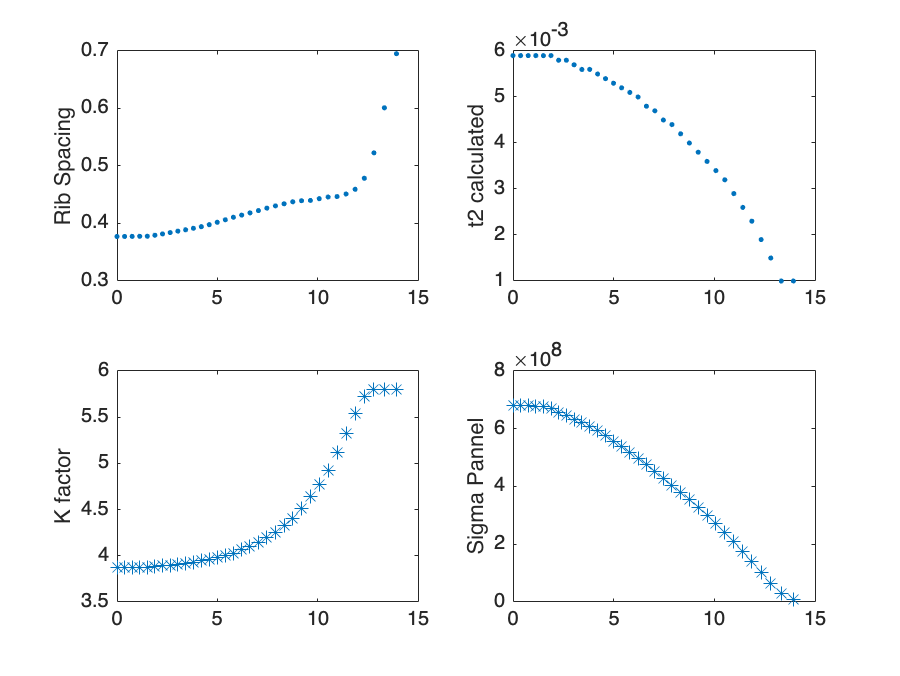


figure; clf;
subplot(2,2,1)
plot(ribLoc,Ls,'.')
ylabel('Rib Spacing')

% Graphs
subplot(2,2,2)
%plot(ribLoc, t2Calc,'x')
%hold on
plot(ribLoc, t2SpanwiseReal,'.')
%hold off
ylabel('t2 calculated')

subplot(2,2,3)
plot(ribLoc, Ks, '*')
ylabel('K factor')
subplot(2,2,4)
plot(ribLoc, sigmaPs, '*')
ylabel('Sigma Pannel')

length(ribLoc)

ans =     34


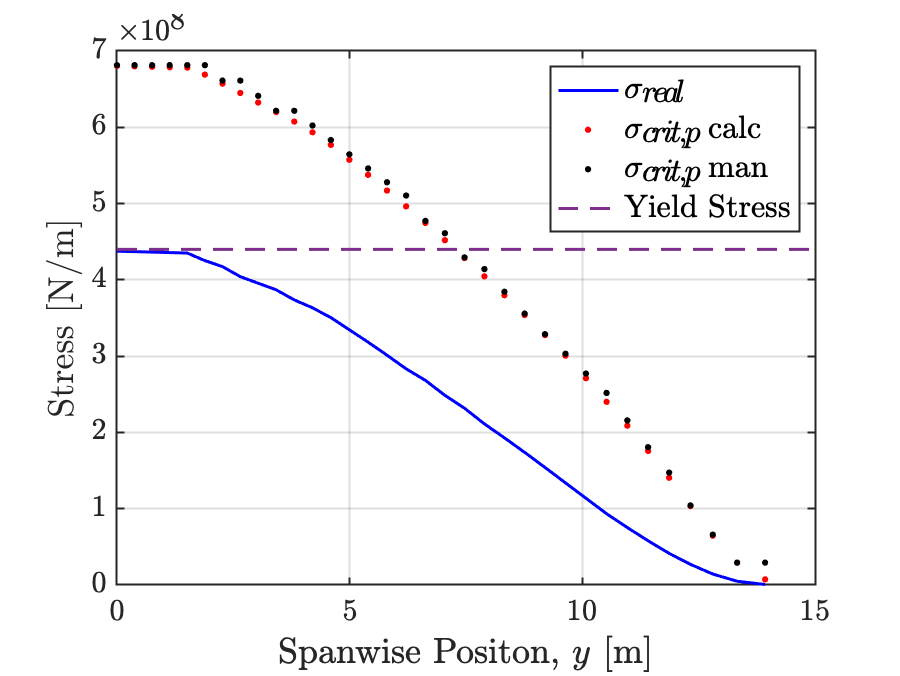


figure; clf;
compYield = 440e6;
subplot(1,1,1)
plot(ribLoc,actual_stress,'b-','LineWidth',1.5,'MarkerSize',8)
hold on
plot(ribLoc, sigmaPs,'r.','LineWidth',1.5,'MarkerSize',8)
%plot(ribLoc, sigma_L, '.')
plot(ribLoc, sigmaPsReal,'k.','LineWidth',1.5,'MarkerSize',8)
plot([0,15], [compYield, compYield],'--','color',[0.4940 0.1840 0.5560],'LineWidth',1.5)
hold off
grid on
box on
ax=gca;ax.LineWidth=1;
set(gca,'FontSize',15)
set(gca,'TickLabelInterpreter','latex')
legend('$\sigma_{real}$','$\sigma_{crit,p}$ calc','$\sigma_{crit,p}$ man','Yield Stress','Interpreter','latex', 'FontSize',16)
xlabel('Spanwise Positon, $y$ [m]', 'Interpreter','latex', 'FontSize',18)
ylabel('Stress [N/m]', 'Interpreter','latex', 'FontSize',18)
saveas(gcf,'stress.png')

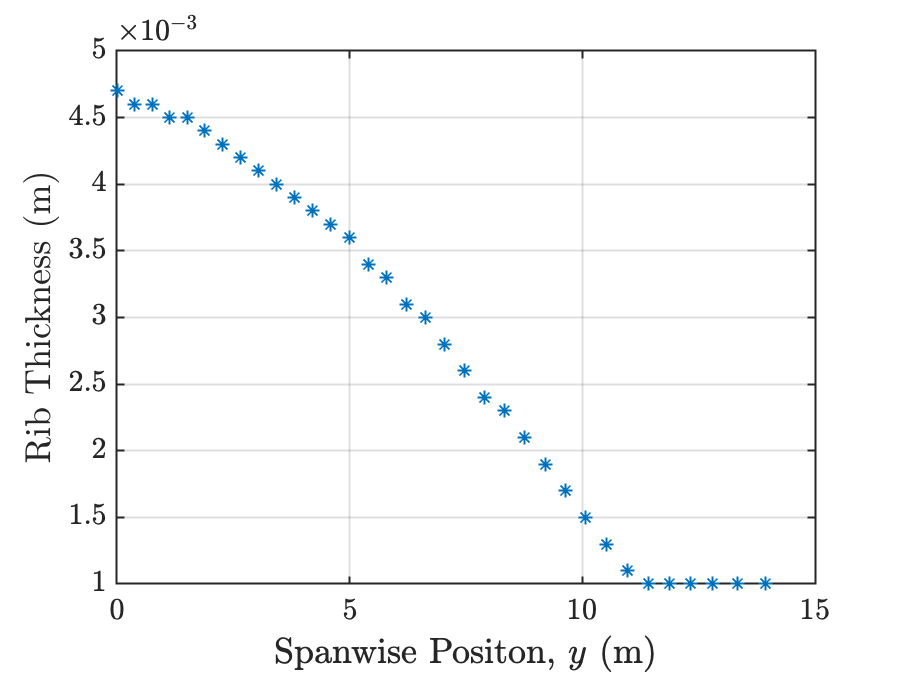


figure; clf;
plot(ribLoc, rib_t,'*','LineWidth',1,'MarkerSize',5)
grid on
box on
ax=gca;ax.LineWidth=1;
set(gca,'FontSize',15)
set(gca,'TickLabelInterpreter','latex')
ylabel('Rib Thickness (m)', 'Interpreter','latex', 'FontSize',18)
xlabel('Spanwise Positon, $y$ (m)', 'Interpreter','latex', 'FontSize',18)
saveas(gcf,'rib Thickness.png')

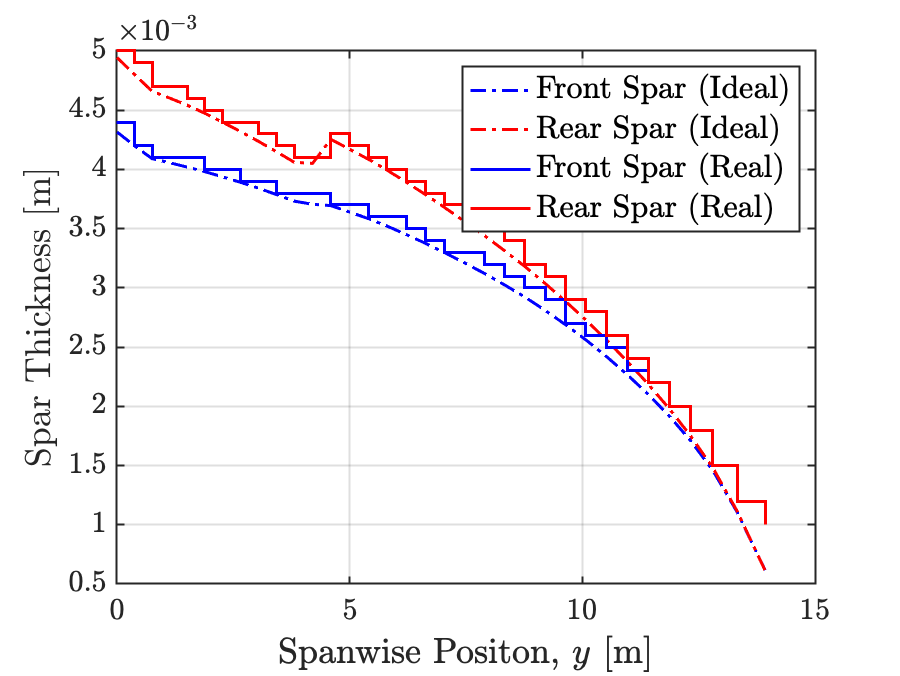


figure; clf;
plot(ribLoc, t_FS_real,'b-.','LineWidth',1.5)
hold on; 
plot(ribLoc, t_RS_real,'r-.','LineWidth',1.5)
stairs(ribLoc, frontSpars_t,'b-','LineWidth',1.5)
stairs(ribLoc, rearSpars_t,'r-','LineWidth',1.5); 
hold off
grid on
box on
ax=gca;ax.LineWidth=1;
set(gca,'FontSize',15)
set(gca,'TickLabelInterpreter','latex')
ylabel('Spar Thickness [m]','Interpreter', 'latex', 'FontSize',18)
xlabel('Spanwise Positon, $y$ [m]', 'Interpreter','latex', 'FontSize',18)
legend('Front Spar (Ideal)','Rear Spar (Ideal)','Front Spar (Real)','Rear Spar (Real)','Interpreter', 'latex', 'FontSize',16)
hold off
saveas(gcf,'spar thickness.png')

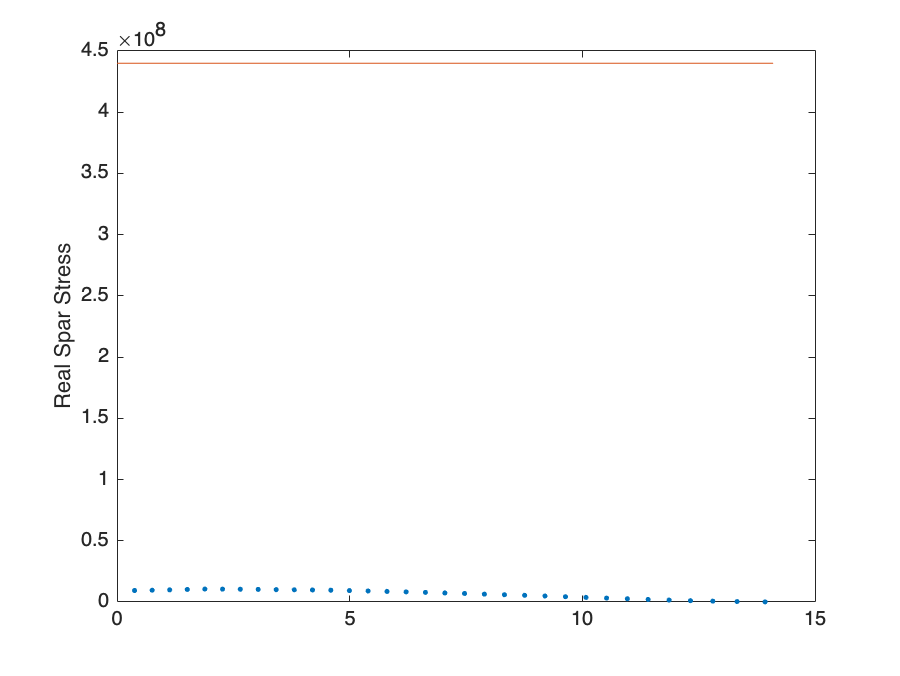


figure; clf;
plot(ribLoc(2:end), fSparRealStress ,'.'); hold on;
%plot(ribLoc(2:end), rSparRealStress,'.'); 
plot([0,14.1], [compYield, compYield]); hold off;
ylabel('Real Spar Stress')

disp(combined)

   0



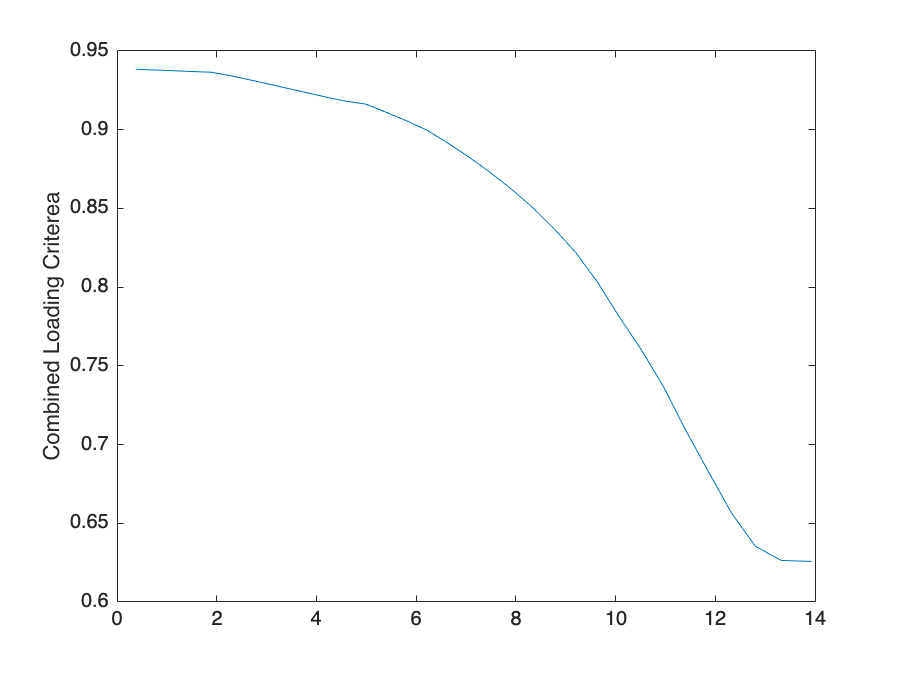


figure; clf;
plot(ribLoc(2:end),combLoad)
ylabel('Combined Loading Criterea')

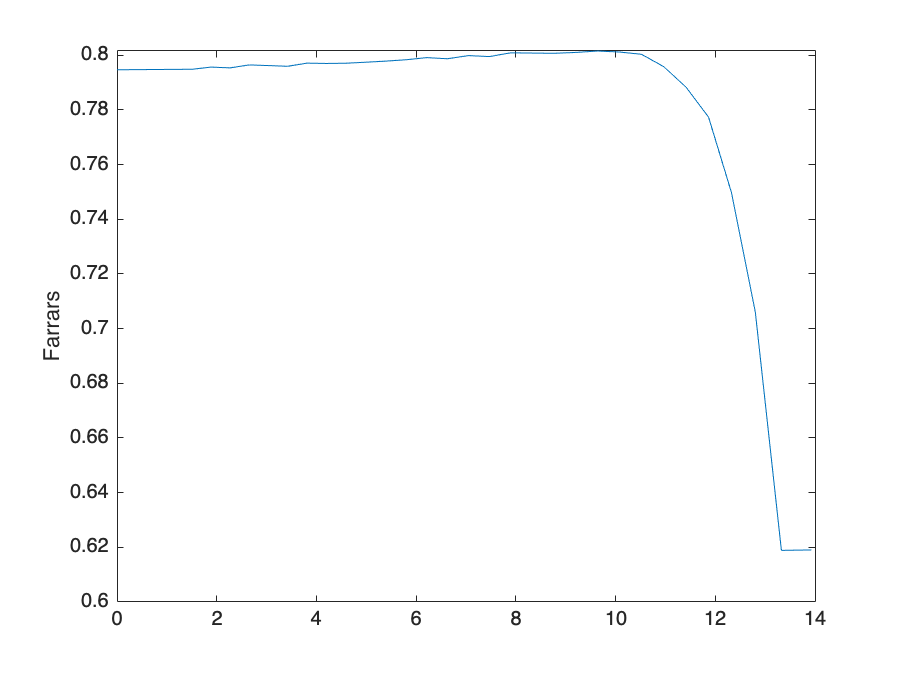


figure; clf;
plot(ribLoc,FarrarsReal)
ylabel('Farrars')

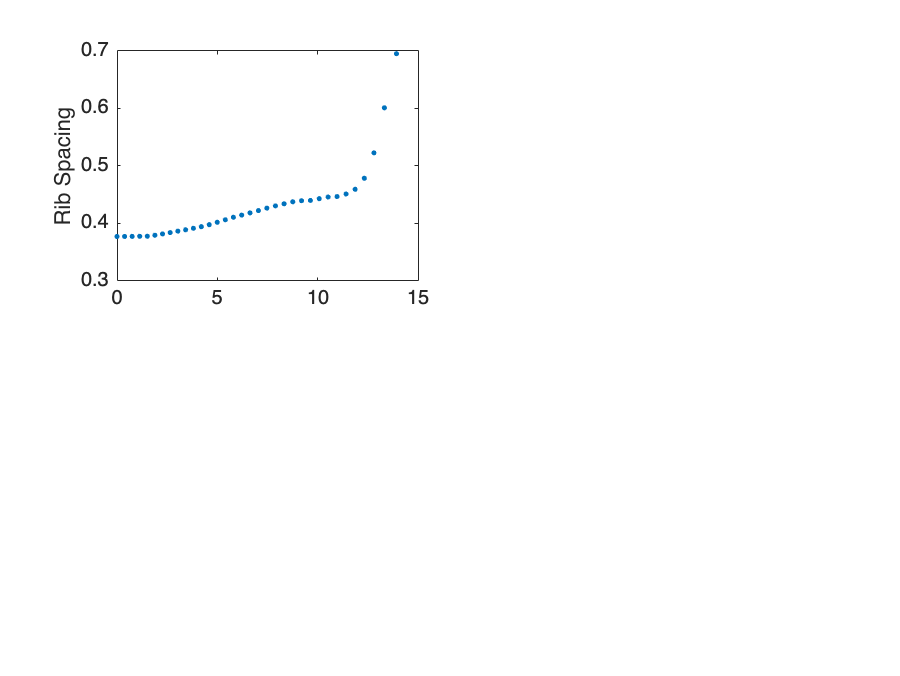


figure; clf;
subplot(2,2,1)
plot(ribLoc,Ls,'.')
ylabel('Rib Spacing')

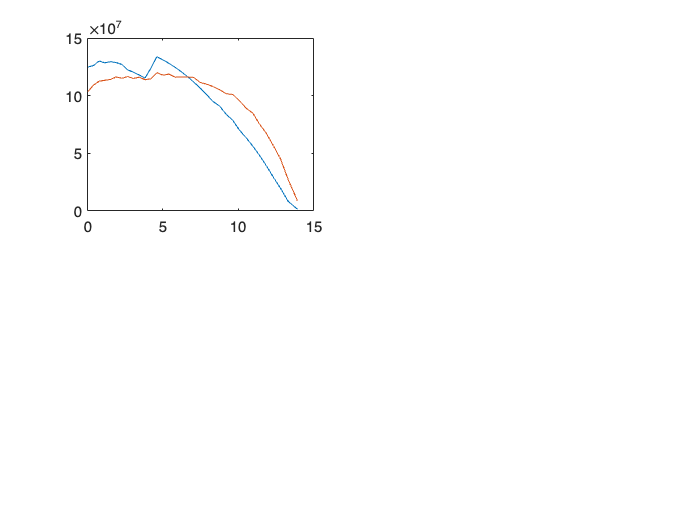


plot(ribLoc, tau_RS); hold on
plot(ribLoc, tau_FS); hold off

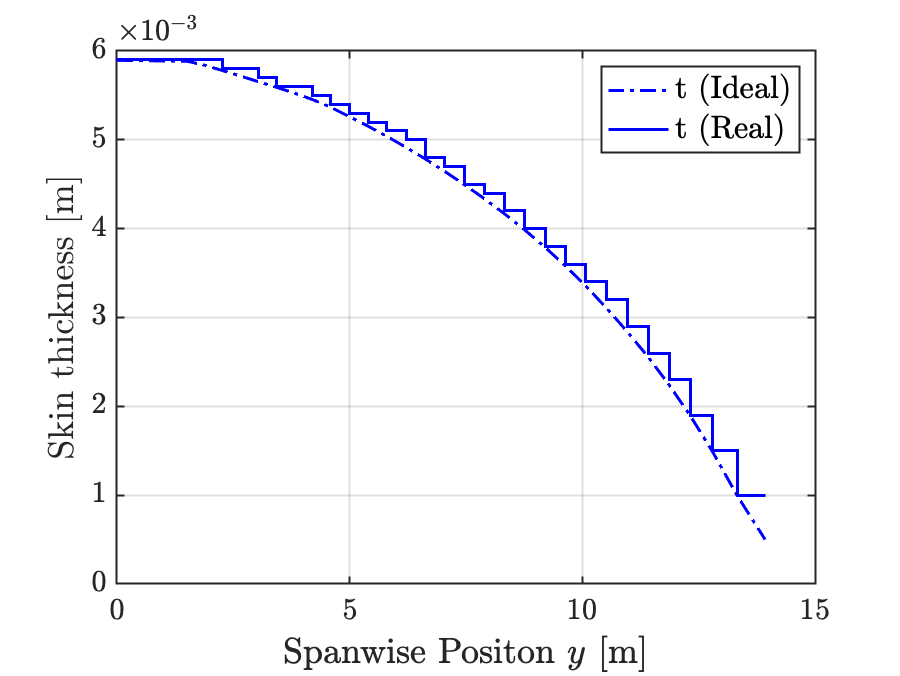


% Graphs
figure; clf;
%plot(ribLoc, t2Calc,'x')
%hold on
plot(ribLoc, t2Calc,'b-.','LineWidth',1.5)
hold on; stairs(ribLoc, t2SpanwiseReal,'b-','LineWidth',1.5); hold off;
box on
grid on
ax=gca;ax.LineWidth=1;
set(gca,'FontSize',15)
set(gca,'TickLabelInterpreter','latex')
ylabel('Skin thickness [m]','Interpreter','latex', 'FontSize',18)
xlabel('Spanwise Positon $y$ [m]', 'Interpreter','latex', 'FontSize',18)
legend('t (Ideal)','t (Real)','Interpreter','latex', 'FontSize',16)
saveas(gcf,'skin thicknessWing.png')

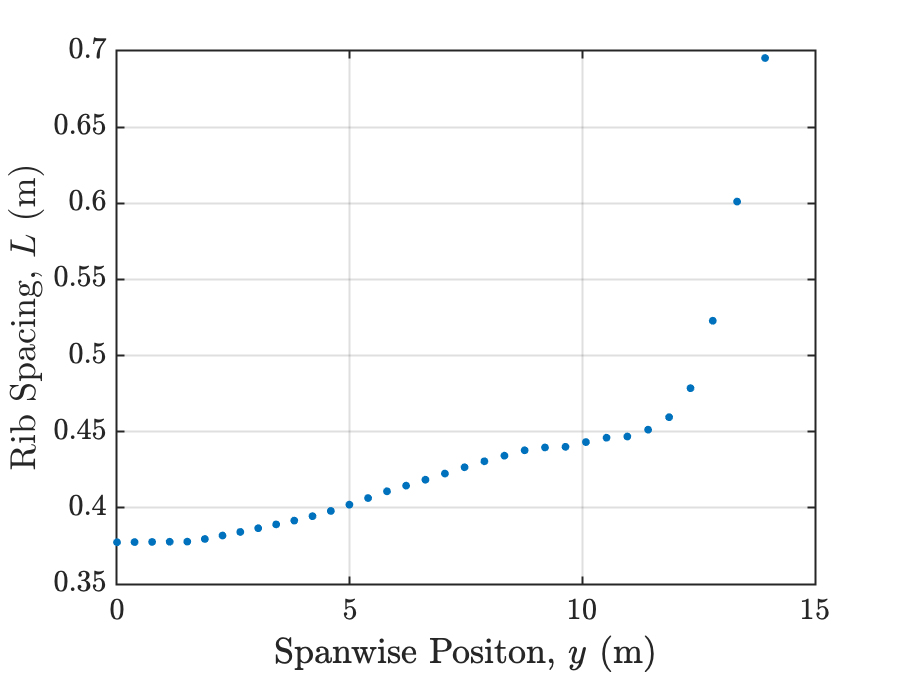


figure; clf;
plot(ribLoc,Ls,'.','markersize',10)
box on
grid on
ax=gca;ax.LineWidth=1;
set(gca,'FontSize',15)
set(gca,'TickLabelInterpreter','latex')
ylabel('Rib Spacing, $L$ (m)','Interpreter','latex', 'FontSize',18)
xlabel('Spanwise Positon, $y$ (m)', 'Interpreter','latex', 'FontSize',18)
saveas(gcf,'rib spacing.png')

N_c Modifcation Comparison

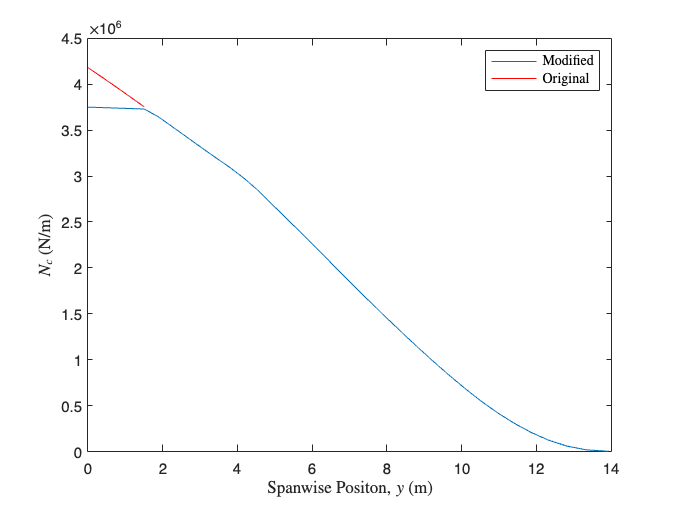

figure; clf;
plot(ribLoc,NCS); hold on
plot(ribLoc(1:5),NCS_old(1:5),'Color','r'); hold off
ylabel('$N_c$ (N/m)', 'Interpreter','latex')
xlabel('Spanwise Positon, $y$ (m)', 'Interpreter','latex')
legend('Modified','Original','Interpreter','latex')

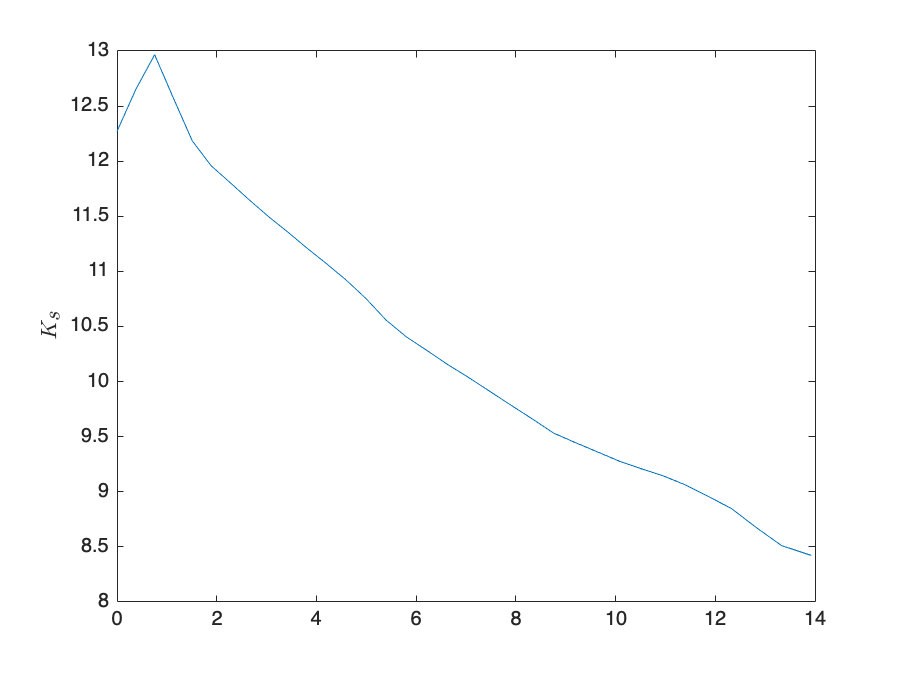

%saveas(gcf,'N_c with ModBox.png')

figure; clf;
plot(ribLoc, sparK)
ylabel('$K_s$','Interpreter','latex')

Lower Surface Design Optimisation

% Only design driver factor is local pannels buckling
BendMomentN = readmatrix('BendingMoment_negative.csv');
Loc = BendMomentN(:,1);
BM2 = BendMomentN(:,2);

yieldLow = 440e6;
h_min = 0.017;
ts_tLower = 0.6;

idx = 0;
j = 0;
for N2 = 4:30
    idx = idx + 1;
    for h = h_min:0.001:0.06
        j = j + 1;
        Ns(idx, j) = N2;
        hS(idx,j) = h;
        massesL(idx,j) = lowerSurface(N2,h,ts_tLower,yieldLow, BM2, Ls, ribLoc,M,Loc);
    end
    j = 0;
end

massesL(massesL==1) = 1e6; % Yields
massesL(massesL==2) = 1e6; % Pannels Buckle
massesL(massesL==3) = 1e6; % Stringers Buckle
massesL(massesL==4) = 1e6; % Torsional instability crit at root


[min_massLow,loc] = min(massesL(:))

min_massLow =      1.463180581826620e+02


loc =     27


[ii,jj] = ind2sub(size(massesL),loc);
opt_N_Lower = Ns(ii)

opt_N_Lower =     30


opt_h_Lower = h_min + 0.001 *(jj -1)

opt_h_Lower =    0.017000000000000


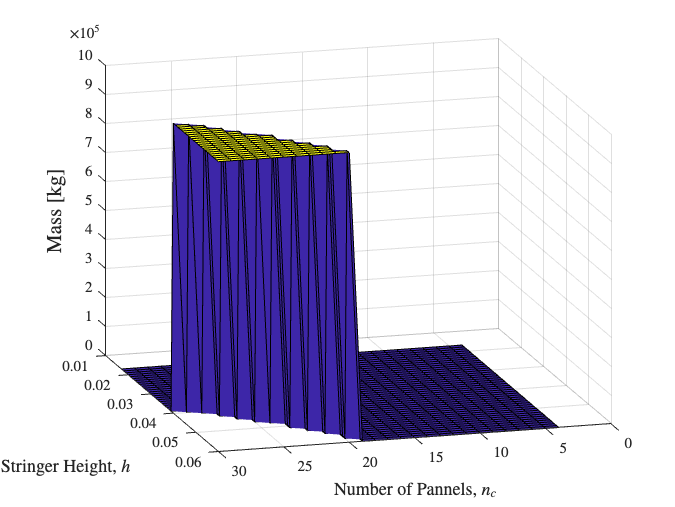

figure; clf;
surf(Ns,hS,massesL)
set(gca,'FontSize',10)
set(gca,'TickLabelInterpreter','latex')
view([-196 19]);
xlabel('Number of Pannels, $n_c$','Interpreter','latex','FontSize',12)
ylabel('Stringer Height, $h$','Interpreter','latex','FontSize',12)
zlabel('Mass [kg]','Interpreter','latex','FontSize',14)

panelMassUp = pannelVol * 2770 

panelMassUp =      3.634254859283047e+02


ribsMass = ribsVol * 2770

ribsMass =      1.240053065648018e+02


sparsMass = sparsVol * 2770

sparsMass =   74.028253118300469


panelMassLow = min_massLow

panelMassLow =      1.463180581826620e+02


dCellMass = 17.1;
Total_Mass = panelMassLow + panelMassUp + ribsMass + sparsMass + dCellMass

Total_Mass =      7.248771037940689e+02



panelUpPer = panelMassUp / Total_Mass * 100

panelUpPer =   50.136151911283235


ribsPer = ribsMass / Total_Mass * 100   

ribsPer =   17.107080071331730


sparsPer = sparsMass / Total_Mass * 100

sparsPer =   10.212524679125639


panelLowPer = panelMassLow / Total_Mass * 100

panelLowPer =   20.185222766289730


dCellPer = dCellMass / Total_Mass * 100

dCellPer =    2.359020571969667


Lower Surface Design Check

% N,h,ts_t, yield,BM,L, ribLoc,M,Loc
BendMomentN = readmatrix('BendingMoment_negative.csv');
Loc2 = BendMomentN(:,1);
BM2 = BendMomentN(:,2);

N = 30; %opt_N_Lower;
h = 0.024; %opt_h_Lower;
E = 73.8e9; %72.4e9;
trig = false;
combinedL = false;
ts_t = 0.6;

root_chord = 4.027;
box_width_root = (0.6-0.15)*root_chord;
web_flange = 0.3; 
pannel_width = box_width_root / N;
h_b = h / pannel_width;
h_root = h;
d_root = (web_flange * h_root);

% Check that K > 3.62 at root
Kroot = K_interp(h_b, ts_t,M);

% Wing box modification to reduce NC
% Fuselage diameter = 2.786
modL = 2.786/2+ 0.2;
boxW_root= 1.9;
boxH_root = 0.4;

boxW_mod = (4.027 - 0.1713.*modL) * (0.6-0.15);
boxH_mod = (4.027 - 0.1713.*modL) * (0.0989+0.0879)/2;
mMod = (boxH_root - boxH_mod) / -modL;
mModW = (boxW_root - boxW_mod) / -modL;

y = 0;

% ts is determined by max stress location, which now at interface of
% changing box structures
box_heightJoin = boxH_root + mMod * y;
box_widthJoin = boxW_root + mModW * y;
NC = interp1(Loc2, BM2, modL) / (box_widthJoin * box_heightJoin);
t2max = abs(NC * (pannel_width^2) / (3.62 * E)) ^ (1/3);
ts_set = ts_t * t2max;


y=0;
for i = 1: length(ribLoc)
    chord = (4.027 - 0.1713*y);
    if y < modL
        box_height = boxH_root + mMod * y;
        box_width = boxW_root + mModW * y;
    else
        box_height = chord*(0.0989+0.0879)/2;
        box_width = (0.6-0.15)*chord;
    end

    NC = interp1(Loc2, BM2, y) / (box_width * box_height)
    % t2 is set using local buckling of a pannel
    t2 = (abs(NC * (pannel_width^2) / (3.62 * E))) ^ (1/3)
    t2_ideal(i) = t2
    if t2 < 0.001
        t2_real = 0.001;
    else
        t2_real = t2;
    end
    
    if i == 1
        % If at the root, calculate stringer thickness
        if t2max > t2
            ts_root = ts_set;
        else
            ts_root = ts_t * t2;
        end
        As_root = (h_root + 2*d_root)*ts_root;
    end
    
    t2Lowers(i) = t2_real;
    T_eq = t2_real + As_root/pannel_width;
    T_eqList(i) = T_eq;
    ts_t = ts_root / t2_real;
    actual_stress = NC / T_eq;
    applied_stress(i) = actual_stress;
    if actual_stress > yield
        mass = 1;
        trig = true;
        break
    end

    K = K_interp(h_b, ts_t,M);
    if i ==1
        k_rootLow = K;
    end
    sigma_pannels = K * E * (t2_real/ pannel_width)^2;
    sigmaPLower(i) = sigma_pannels;
    I_A = h^2 * h_b * ts_t * (0.633+ 0.37* h_b* ts_t) / (1.6 *h_b * ts_t + 1)^2;
    F = ((K * (t2/pannel_width)^2 * pi^2 * I_A)^(1/4) ) / (t2* (1 + 1.6*h_b * ts_t))^(1/2);
    farrarsLow(i) = F;
    sigma_stringers = F * sqrt(abs(NC * E / Ls(i)));
    sigmaSLower(i) = sigma_stringers;
    if sigma_pannels < actual_stress
        mass = 2; % Pannels buckle below applied stress
        trig = true;
        break
    elseif sigma_stringers < actual_stress
        mass = 3; % Stringers buckle below applied stress
        trig = true;
        break
    end
    if y>14.1
        break
    end
    % Combined Loading
%     q_T = interp1(Loc, Torque, y) / (2*box_width*box_height);
%     Rc = 1/K;
%     tau0 = q_T/t2_real;
%     Rs = tau0 / trescaYield;
%     combLoadL(i) = Rs^2 + Rc;
%     if combLoadL(i) > 0.99
%         combinedL = true;
%     end
    y = ribLoc(i);
end

NC =     -1.470538800000000e+06


t2 =    0.002718227348064


t2_ideal =    0.002718227348064


NC =     -1.470538800000000e+06


t2 =    0.002718227348064


t2_ideal =    0.002718227348064   0.002718227348064


NC =     -1.466808437812079e+06


t2 =    0.002715926930750


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750


NC =     -1.462835421523574e+06


t2 =    0.002713472581861


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861


NC =     -1.458628484806615e+06


t2 =    0.002710868878602


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602


NC =     -1.454201355573518e+06


t2 =    0.002708123484691


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691


NC =     -1.418547469313902e+06


t2 =    0.002685807647518


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518


NC =     -1.373184426419445e+06


t2 =    0.002656867551511


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511


NC =     -1.327026181316345e+06


t2 =    0.002626758293186


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186


NC =     -1.280149508648332e+06


t2 =    0.002595457048625


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625


NC =     -1.233925000503041e+06


t2 =    0.002563833804693


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693


NC =     -1.187853189913755e+06


t2 =    0.002531519076617


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617


NC =     -1.160444293634633e+06


t2 =    0.002511896345483


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483


NC =     -1.139441439637722e+06


t2 =    0.002496649738509


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509


NC =     -1.074954917800511e+06


t2 =    0.002448633002695


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695


NC =     -1.010746184504232e+06


t2 =    0.002398875184511


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511


NC =     -9.451603523639869e+05


t2 =    0.002345824116779


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779


NC =     -8.783209611228628e+05


t2 =    0.002289169920917


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917


NC =     -8.105342123191935e+05


t2 =    0.002228695478452


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452


NC =     -7.419886191076492e+05


t2 =    0.002164010496496


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496


NC =     -6.736949007586977e+05


t2 =    0.002095469617773


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773


NC =     -6.063225188393630e+05


t2 =    0.002023150455270


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270


NC =     -5.391794951205337e+05


t2 =    0.001945530622234


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234


NC =     -4.727326633512286e+05


t2 =    0.001862082071259


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234   0.001862082071259


NC =     -4.075014237162017e+05


t2 =    0.001772161613430


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234   0.001862082071259   0.001772161613430


NC =     -3.442910400727285e+05


t2 =    0.001675337032785


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234   0.001862082071259   0.001772161613430   0.001675337032785


NC =     -2.838903573022417e+05


t2 =    0.001571003534481


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234   0.001862082071259   0.001772161613430   0.001675337032785   0.001571003534481


NC =     -2.266607007784102e+05


t2 =    0.001457423240767


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234   0.001862082071259   0.001772161613430   0.001675337032785   0.001571003534481   0.001457423240767


NC =     -1.745498748413262e+05


t2 =    0.001335877993451


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234   0.001862082071259   0.001772161613430   0.001675337032785   0.001571003534481   0.001457423240767   0.001335877993451


NC =     -1.282698643036477e+05


t2 =    0.001205503549405


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234   0.001862082071259   0.001772161613430   0.001675337032785   0.001571003534481   0.001457423240767   0.001335877993451   0.001205503549405


NC =     -8.769110399755345e+04


t2 =    0.001061969704598


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234   0.001862082071259   0.001772161613430   0.001675337032785   0.001571003534481   0.001457423240767   0.001335877993451   0.001205503549405   0.001061969704598


NC =     -5.367778736343322e+04


t2 =      9.016925543173786e-04


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234   0.001862082071259   0.001772161613430   0.001675337032785   0.001571003534481   0.001457423240767   0.001335877993451   0.001205503549405   0.001061969704598   0.000901692554317


NC =     -2.704557316215339e+04


t2 =      7.175062330852080e-04


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234   0.001862082071259   0.001772161613430   0.001675337032785   0.001571003534481   0.001457423240767   0.001335877993451   0.001205503549405   0.001061969704598   0.000901692554317   0.000717506233085


NC =     -8.948171425538601e+03


t2 =      4.962551729164443e-04


t2_ideal =    0.002718227348064   0.002718227348064   0.002715926930750   0.002713472581861   0.002710868878602   0.002708123484691   0.002685807647518   0.002656867551511   0.002626758293186   0.002595457048625   0.002563833804693   0.002531519076617   0.002511896345483   0.002496649738509   0.002448633002695   0.002398875184511   0.002345824116779   0.002289169920917   0.002228695478452   0.002164010496496   0.002095469617773   0.002023150455270   0.001945530622234   0.001862082071259   0.001772161613430   0.001675337032785   0.001571003534481   0.001457423240767   0.001335877993451   0.001205503549405   0.001061969704598   0.000901692554317   0.000717506233085   0.000496255172916


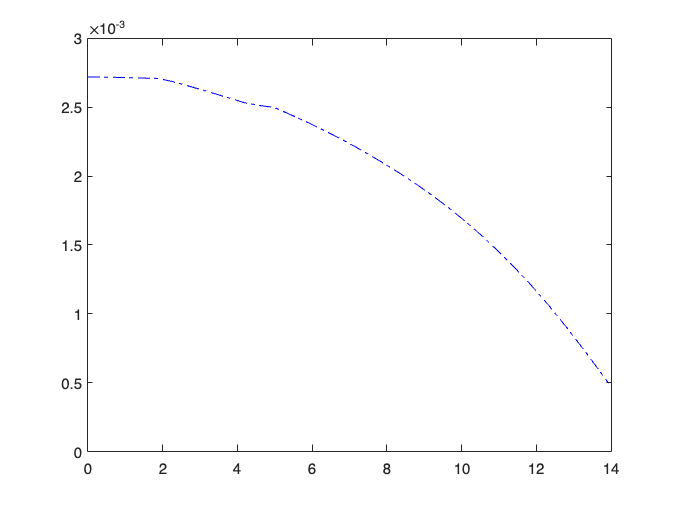


if Kroot < 3.62
    mass = 4; 
elseif trig == false
    ribLoc2 = [ribLoc, 14.1];
    pannelVol = PannelsVol(N,ribLoc2,T_eqList);
    mass = pannelVol * 2770 ;%2800;
end
% Sus why is skin thickness trying to be 0 at the root?
figure; clf;
plot(ribLoc, t2_ideal, 'b-.','LineWidth',1.5)

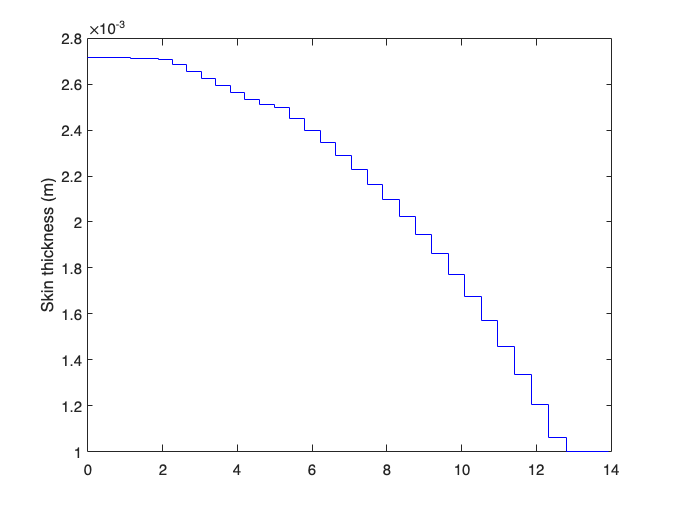

hold on
stairs(ribLoc, t2Lowers, 'b-','LineWidth',1.5)
hold off
box on
grid on
ax=gca;ax.LineWidth=1;
set(gca,'FontSize',15)
set(gca,'TickLabelInterpreter','latex')
ylabel('Skin thickness [m]','Interpreter','latex', 'FontSize',18)
xlabel('Spanwise Positon $y$ [m]', 'Interpreter','latex', 'FontSize',18)
legend('t (Ideal)','t (Real)','Interpreter','latex', 'FontSize',16)


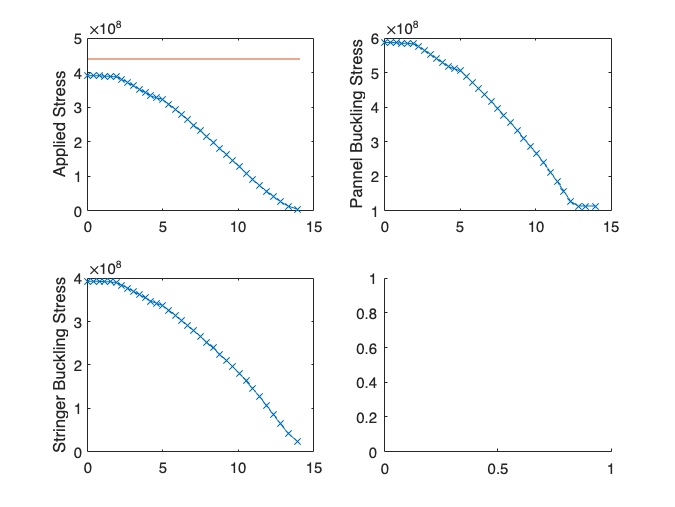


figure; clf;
subplot(2,2,1)
plot(ribLoc, abs(applied_stress),'x-')
hold on; plot([0,14.1], [compYield, compYield]); hold off
ylabel('Applied Stress')

subplot(2,2,2)
plot(ribLoc, sigmaPLower,'x-')
ylabel('Pannel Buckling Stress')

subplot(2,2,3)
plot(ribLoc, sigmaSLower,'x-')
ylabel('Stringer Buckling Stress')

subplot(2,2,4)

plot(ribLoc, combLoadL)

Unrecognized function or variable 'combLoadL'.

ylabel('Combing Loading Criterea')